clc
clear all
close all
 

A = [[0,2,0,0,0.5,0,0,0];
    [0,0,1,0,0,0,0,0];
    [0,0,0,0.5,0,0,0,0];
    [0,0,0,0,1.5,0,0,0];
    [1,0,0,0,0,2,0,0];
    [0,0,0,0,0,0,0.5,0];
    [0,0,0,0,0,0,1,1];
    [0,0,0,0,0,2,0,0]]

A =          0    2.0000         0         0    0.5000         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0
         0         0         0         0    1.5000         0         0         0
    1.0000         0         0         0         0    2.0000         0         0
         0         0         0         0         0         0    0.5000         0
         0         0         0         0         0         0    1.0000    1.0000
         0         0         0         0         0    2.0000         0         0


eig(A)

ans =   -0.9496 + 0.5757i
  -0.9496 - 0.5757i
   1.1844 + 0.0000i
   0.3574 + 0.9484i
   0.3574 - 0.9484i
  -0.2328 + 0.7926i
  -0.2328 - 0.7926i
   1.4656 + 0.0000i


G = digraph(A)

G =   digraph with properties:

    Edges: [11×2 table]
    Nodes: [8×0 table]


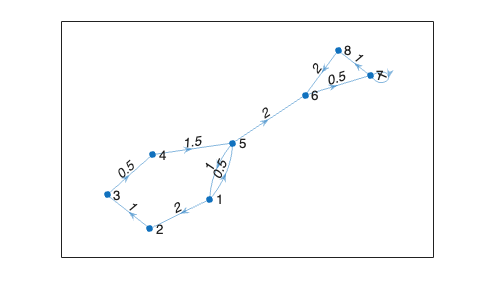


p = plot(G, 'Layout', 'force');
p.EdgeLabel = G.Edges.Weight;


D_in = diag([1,2,1,0.5,2,4,1.5,1])

D_in =     1.0000         0         0         0         0         0         0         0
         0    2.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0
         0         0         0         0    2.0000         0         0         0
         0         0         0         0         0    4.0000         0         0
         0         0         0         0         0         0    1.5000         0
         0         0         0         0         0         0         0    1.0000


D_out = diag([2.5,1,1,1.5,3,0.5,2,2])

D_out =     2.5000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    1.5000         0         0         0         0
         0         0         0         0    3.0000         0         0         0
         0         0         0         0         0    0.5000         0         0
         0         0         0         0         0         0    2.0000         0
         0         0         0         0         0         0         0    2.0000


D_out_inv = D_out^-1

D_out_inv =     0.4000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    0.6667         0         0         0         0
         0         0         0         0    0.3333         0         0         0
         0         0         0         0         0    2.0000         0         0
         0         0         0         0         0         0    0.5000         0
         0         0         0         0         0         0         0    0.5000


A_bar = D_out_inv*A

A_bar =          0    0.8000         0         0    0.2000         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0
         0         0         0         0    1.0000         0         0         0
    0.3333         0         0         0         0    0.6667         0         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    0.5000    0.5000
         0         0         0         0         0    1.0000         0         0


G = digraph(A_bar)

G =   digraph with properties:

    Edges: [11×2 table]
    Nodes: [8×0 table]


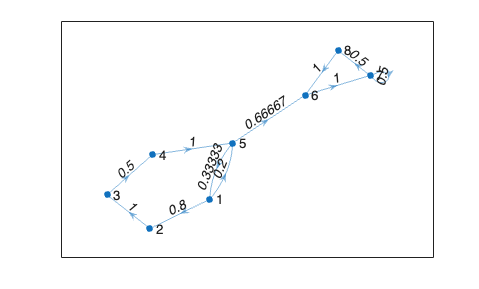

p = plot(G, 'Layout', 'force');
p.EdgeLabel = G.Edges.Weight;

eig(A_bar)

ans =   -0.5566 + 0.3805i
  -0.5566 - 0.3805i
   0.6889 + 0.0000i
   0.2122 + 0.6170i
   0.2122 - 0.6170i
  -0.2500 + 0.6614i
  -0.2500 - 0.6614i
   1.0000 + 0.0000i


x0 =[1;0;0.5;0;1.5;0;0;0]

x0 =     1.0000
         0
    0.5000
         0
    1.5000
         0
         0
         0


x0_mean = mean(x0)

x0_mean = 0.3750

K = 20;
x_inf = Simulate_Consensus(A_bar,A_bar,x0, K, 'sync')

x_inf = 1.0e-03 *

    0.3819
    0.5145
    0.2674
    0.1668
    0.5942
         0
         0
         0


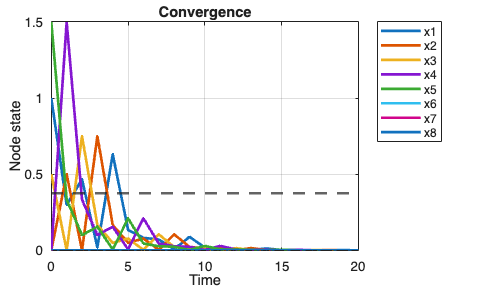

X = Simulate_Trajectory(A_bar, A_bar, x0, K, 'sync');

figure;
plot(0:K, X', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('Convergence')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6','x7','x8','Location', 'northeastoutside');

A_rev = [[0,2,0,0,0.5,0,0,0];
         [0,0,1,0,0,0,0,0];
         [0,0,0,0.5,0,0,0,0];
         [0,0,0,0,1.5,0,0,0];
         [1,0,0,0,0,0,0,0];
         [0,0,0,0,2,0,0.5,0];
         [0,0,0,0,0,0,1,0];
         [0,0,0,0,0,2,1,0]]

A_rev =          0    2.0000         0         0    0.5000         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    0.5000         0         0         0         0
         0         0         0         0    1.5000         0         0         0
    1.0000         0         0         0         0         0         0         0
         0         0         0         0    2.0000         0    0.5000         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0    2.0000    1.0000         0


eig(A_rev)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.9496 + 0.5757i
  -0.9496 - 0.5757i
   1.1844 + 0.0000i
   0.3574 + 0.9484i
   0.3574 - 0.9484i
   1.0000 + 0.0000i


G_rev = digraph(A_rev)

G_rev =   digraph with properties:

    Edges: [11×2 table]
    Nodes: [8×0 table]


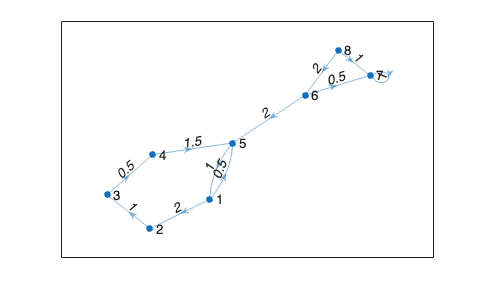


p = plot(G_rev, 'Layout', 'force');
p.EdgeLabel = G_rev.Edges.Weight;


D_in_rev = diag([1, 2, 1, 0.5, 4, 2, 2.5, 0]);
D_out_rev = diag([2.5, 1, 0.5, 1.5, 1, 2.5, 1, 3]);
D_out_inv_rev = D_out_rev^-1

D_out_inv_rev =     0.4000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0    2.0000         0         0         0         0         0
         0         0         0    0.6667         0         0         0         0
         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0    0.4000         0         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0    0.3333


A_bar_rev = D_out_inv_rev*A_rev

A_bar_rev =          0    0.8000         0         0    0.2000         0         0         0
         0         0    1.0000         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0
         0         0         0         0    1.0000         0         0         0
    1.0000         0         0         0         0         0         0         0
         0         0         0         0    0.8000         0    0.2000         0
         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0    0.6667    0.3333         0


G_rev = digraph(A_bar_rev)

G_rev =   digraph with properties:

    Edges: [11×2 table]
    Nodes: [8×0 table]


eig(A_bar_rev)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.8070 + 0.5358i
  -0.8070 - 0.5358i
   1.0000 + 0.0000i
   0.3070 + 0.8708i
   0.3070 - 0.8708i
   1.0000 + 0.0000i


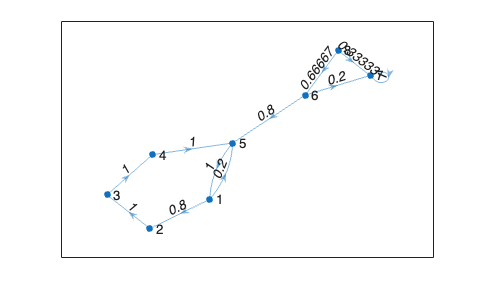

p = plot(G_rev, 'Layout', 'force');
p.EdgeLabel = G_rev.Edges.Weight;

eig(A_bar_rev)

ans =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -0.8070 + 0.5358i
  -0.8070 - 0.5358i
   1.0000 + 0.0000i
   0.3070 + 0.8708i
   0.3070 - 0.8708i
   1.0000 + 0.0000i


K = 200;
x_inf = Simulate_Consensus(A_bar_rev,A_bar_rev,x0, K, 'sync')

x_inf =     0.6585
    0.6601
    0.6583
    0.6594
    0.6593
    0.5275
         0
    0.3511


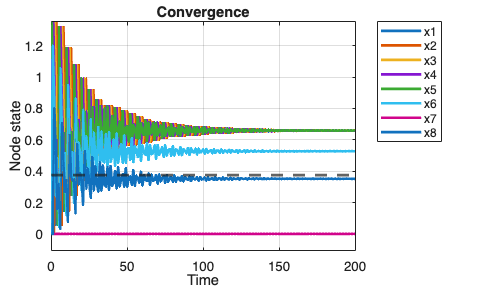

X = Simulate_Trajectory(A_bar_rev, A_bar_rev, x0, K, 'sync');

figure;
plot(0:K, X', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
ylim('padded'); % Aggiunge automaticamente un margine sopra e sotto ai dati
title('Convergence')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6','x7','x8','Location', 'northeastoutside');